# VAJA 1

clear all; clc;

Naloga 1

N = 1000000; %st vzorcev
x1 = ones(1, N);
y1 = ones(1, N);

for i = 1:N
    while ((x1(i)^2 + y1(i)^2) >= 1)
        x1(i) = 2 * rand() - 1;
        y1(i) = 2 * rand() - 1;
    end
end
P1=2*sqrt(1-(x1.^2 + y1.^2)); %dolžina tetive

Ploti:

t1=tiledlayout(1,2);
nexttile;
histogram(P1, 100, 'Normalization', 'pdf');
title('1 pdf')
axis square

nexttile;
histogram(P1, 100, 'Normalization', 'CDF');
title('1 cdf')
axis square

Verjetnost:

Prob1 = sum(P1>sqrt(3))/N

Prob1 = 0.2504

Naloga 2

a2 = rand(1, N)*2*pi;
x2 = cos(a2);
y2 = sin(a2);
P2 = sqrt((x2 + 1).^2+y2.^2);

Ploti:

t2=tiledlayout(1,2);
nexttile;
histogram(P2, 100, 'Normalization', 'pdf');
title('2 pdf')
axis square

nexttile;
histogram(P2, 100, 'Normalization', 'CDF');
title('2 cdf')
axis square

Verjetnost

Prob2 = sum(P2>sqrt(3))/N

Prob2 = 0.3334

Naloga 3

y3 = rand(1, N) * 2 - 1;
P3 = 2 * sqrt(1 - y3.^2);

Ploti:

t3=tiledlayout(1,2);
nexttile;
histogram(P3, 100, 'Normalization', 'pdf');
title('3 pdf')
axis square

nexttile;
histogram(P3, 100, 'Normalization', 'CDF');
title('3 cdf')
axis square

Verjetnost

Prob3 = sum(P3>sqrt(3))/N

Prob3 = 0.5000

Naloga 4

a4 = rand(1, N)*2*pi;
b4 = rand(1, N)*2*pi;
xA4 = cos(a4);
yA4 = sin(a4);
xB4 = cos(b4);
yB4 = sin(b4);
P4 = sqrt((xA4-xB4).^2+(yA4-yB4).^2);

Ploti:

t4=tiledlayout(1,2);
nexttile;
histogram(P4, 100, 'Normalization', 'pdf');
title('4 pdf')
axis square

nexttile;
histogram(P4, 100, 'Normalization', 'CDF');
title('4 cdf')
axis square

Verjetnost

Prob4 = sum(P4>sqrt(3))/N

Prob4 = 0.3332

Naloga 5

N = 10000;
x5 = zeros(1, N);
y5 = zeros(1, N);
a5 = zeros(1, N);
r=1;
c=1;

for i = 1:N
    while ((x5(i)^2+y5(i)^2)~=1)
        a5(i) = rand()*2*pi;
        x5(i) = cos(a5(i));
        y5(i) = sin(a5(i));
    end
    M5(i)=sqrt(x5(i)^2+y5(i)^2);
      while M5(i)>0
           P5(c)=2*sqrt(r^2-M5(i)^2);
           M5(i)=M5(i)-(1/N);
           c =c+1;
      end
end
N =c;

Ploti:

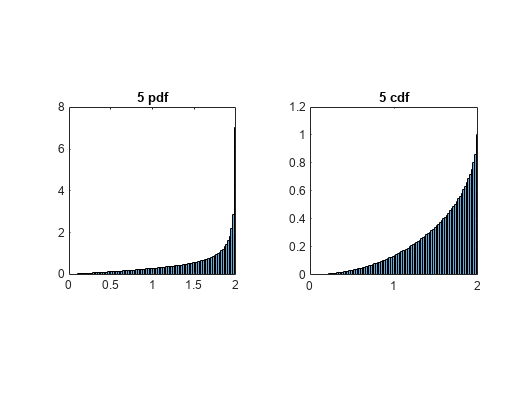

t5=tiledlayout(1,2);
nexttile;
histogram(P5, 100, 'Normalization', 'pdf');
title('5 pdf')
axis square

nexttile;
histogram(P5, 100, 'Normalization', 'CDF');
title('5 cdf')
axis square

Verjetnost

Prob5=sum(P5>sqrt(3))/(c)

Prob5 = 0.5000